clear;clc;close all;

sq_pt = 250;
parts = round(sqrt(sq_pt));
max_gen = 400;

epsilon = 1e-6;
tau_d = 0.01;
pop_size = 300;
dim = 3;
mutation_factor=0.831987414;
crossover_rate=0.887292888;
seed = 'shuffle';
print_stat = false;
verbose = false;
visual_properties = struct('show_visual',false, ...
    'save_visual', false, ...
    'file_name', 'hde.avi');


print_stat = false;
verbose = true;

rngseed = rng(seed);
disp(rngseed.Seed)

   2031147035



basename = 'hde';
us = '_';
extension = '.avi';

visual_properties = struct('show_visual',false, ...
    'save_visual', false, ...
    'file_name', [basename,us,num2str(sq_pt),us,num2str(max_gen),us,num2str(rngseed.Seed),extension]);


% Define boundaries
% % Problem 1 and 5
% boundaries = repmat([-10, 10], dim, 1);
% % Problem 2
% boundaries = [-1,3;-17,4];
% % Problem 4
% boundaries = repmat([-40, 40], dim, 1);
% % Problem 7
boundaries = [0,2;-10,10;-1,1];

hdeopt = HDE(boundaries,pop_size,parts,max_gen,mutation_factor,crossover_rate,epsilon,tau_d,seed);

[final_root,final_score,num_cluster] = hdeopt.DE_evaluation(verbose,print_stat,visual_properties)

Number of clusters containing root: 141

====== Cluster 1 ======
Roots =
    {[0 0.5078 -0.8750]}


====== Cluster 2 ======
Roots =
    {[0 0.5078 -0.8750]}    {[0.1250 0.4520 -0.8750]}


====== Cluster 3 ======
Roots =
    {[0 0.5078 -0.8750]}    {[0.1250 0.4520 -0.8750]}    {[1.2500 0.4169 -0.8750]}


====== Cluster 4 ======
Roots =
    {[0 0.5078 -0.8750]}    {[0.1250 0.4520 -0.8750]}    {[1.2500 0.4169 -0.8750]}    {[1.2693 0.4169 -0.8750]}


====== Cluster 5 ======
Roots =
    {[0 0.5078 -0.8750]}    {[0.1250 0.4520 -0.8750]}    {[1.2500 0.4169 -0.8750]}    {[1.2693 0.4169 -0.8750]}    {[1.3750 0.7374 -0.8750]}


====== Cluster 6 ======
Roots =
    {[0 0.5078 -0.8750]}    {[0.1250 0.4520 -0.8750]}    {[1.2500 0.4169 -0.8750]}    {[1.2693 0.4169 -0.8750]}    {[1.3750 0.7374 -0.8750]}    {[1.8750 1.1298 -0.8750]}


====== Cluster 7 ======
Roots =
    {[0 0.5078 -0.8750]}    {[0.1250 0.4520 -0.8750]}    {[1.2500 0.4169 -0.8750]}    {[1.2693 0.4169 -0.8750]}    {[1.3750 0.7374 -0.8750

final_root =     1.2995    0.5258   -0.6428
    1.9833    0.9834   -0.0168
    1.5337   -1.6481    0.4996
    1.9814   -2.1722    0.7757


final_score =    -1.0000   -1.0000   -1.0000   -1.0000


num_cluster = 141

% hdeopt.visualization2D(visual_properties)
% pause(5);
% close;


he = hdeopt.slice_hypercube(boundaries(:,1),boundaries(:,2),parts)

he = he(:,:,1) =

  Columns 1 through 3,276

         0    0.1250    0.2500    0.3750    0.5000    0.6250    0.7500    0.8750    1.0000    1.1250    1.2500    1.3750    1.5000    1.6250    1.7500    1.8750         0    0.1250    0.2500    0.3750    0.5000    0.6250    0.7500    0.8750    1.0000    1.1250    1.2500    1.3750    1.5000    1.6250    1.7500    1.8750         0    0.1250    0.2500    0.3750    0.5000    0.6250    0.7500    0.8750    1.0000    1.1250    1.2500    1.3750    1.5000    1.6250    1.7500    1.8750         0    0.1250    0.2500    0.3750    0.5000    0.6250    0.7500    0.8750    1.0000    1.1250    1.2500    1.3750    1.5000    1.6250    1.7500    1.8750         0    0.1250    0.2500    0.3750    0.5000    0.6250    0.7500    0.8750    1.0000    1.1250    1.2500    1.3750    1.5000    1.6250    1.7500    1.8750         0    0.1250    0.2500    0.3750    0.5000    0.6250    0.7500    0.8750    1.0000    1.1250    1.2500    1.3750    1.5000    1.6250    1.7500    1

cluster = {};
for hypercube_id = 1:size(he, 2)
    X0 = he(:,hypercube_id,:);
    X0 = reshape(X0, [], size(X0, 3));
    
    F_list = zeros(dim,size(X0,1));
    for i = 1:size(X0,1)
        F_list(:,i) = hdeopt.system_equations(X0(i,:));
    end
    
    product_combination = zeros(size(F_list, 1), nchoosek(size(F_list, 2), 2));
    for i = 1:size(F_list, 1)
        combinations = nchoosek(F_list(i,:), 2);
        product_combination(i,:) = prod(combinations, 2)';
    end
    change_sign_1 = any(product_combination < 0, 1);
    change_sign_2 = any(product_combination < 0, 2);
    if all(change_sign_2)
        cluster{end+1} = X0;
    end
end
cluster = cat(3, cluster{:});

cluster = cluster(:,:,1) =

         0         0   -1.0000
    0.1250         0   -1.0000
         0    1.2500   -1.0000
    0.1250    1.2500   -1.0000
         0         0   -0.8750
    0.1250         0   -0.8750
         0    1.2500   -0.8750
    0.1250    1.2500   -0.8750


cluster(:,:,2) =

    0.1250         0   -1.0000
    0.2500         0   -1.0000
    0.1250    1.2500   -1.0000
    0.2500    1.2500   -1.0000
    0.1250         0   -0.8750
    0.2500         0   -0.8750
    0.1250    1.2500   -0.8750
    0.2500    1.2500   -0.8750


cluster(:,:,3) =

    1.1250         0   -1.0000
    1.2500         0   -1.0000
    1.1250    1.2500   -1.0000
    1.2500    1.2500   -1.0000
    1.1250         0   -0.8750
    1.2500         0   -0.8750
    1.1250    1.2500   -0.8750
    1.2500    1.2500   -0.8750


cluster(:,:,4) =

    1.2500         0   -1.0000
    1.3750         0   -1.0000
    1.2500    1.2500   -1.0000
    1.3750    1.2500   -1.0000
    1.2500         0   -0.8750
    1.3750   

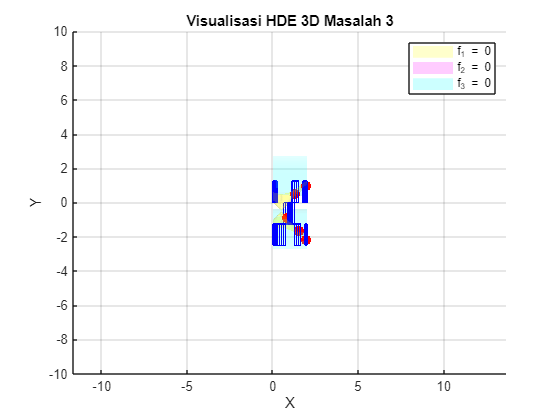

% Membuat plot 3D
figure;

% Step 2: Generate a 3D grid of points
[x1, x2, x3] = meshgrid(0:0.1:2, -10:0.1:10, -1:0.1:1);

% Step 3: Evaluate the functions over the 3D grid
f1_vals = zeros(size(x1));
f2_vals = zeros(size(x1));
f3_vals = zeros(size(x1));

for i = 1:numel(x1)
    F = nesfunc.system_equations3([x1(i); x2(i); x3(i)]);
    f1_vals(i) = F(1);
    f2_vals(i) = F(2);
    f3_vals(i) = F(3);
end

% Step 4: Create 3D isosurface plots
figure;

% Plot isosurface for f1 = 0
iso1 = isosurface(x1, x2, x3, f1_vals, 0);
patch(iso1, 'FaceColor', 'yellow', 'EdgeColor', 'none', 'FaceAlpha', 0.2); % Red color for f1 = 0

% Adjust properties for isosurface 1
camlight('headlight'); % Adjust lighting for better visibility
lighting gouraud; % Use Gouraud lighting for smoother appearance
grid on; % Add grid lines for depth perception

hold on;

% Plot isosurface for f2 = 0
iso2 = isosurface(x1, x2, x3, f2_vals, 0);
patch(iso2, 'FaceColor', 'magenta', 'EdgeColor', 'none', 'FaceAlpha', 0.2); % Red color for f2 = 0

% Adjust properties for isosurface 2
camlight('headlight'); % Adjust lighting for better visibility
lighting gouraud; % Use Gouraud lighting for smoother appearance
grid on; % Add grid lines for depth perception

% Plot isosurface for f3 = 0
iso3 = isosurface(x1, x2, x3, f3_vals, 0);
patch(iso3, 'FaceColor', 'cyan', 'EdgeColor', 'none', 'FaceAlpha', 0.2); % Red color for f3 = 0

% Plot solutions from the table
solutions = [0.825297, -0.859034, -0.151946;
             1.299490, 0.525835, -0.642769;
             1.533662, -1.648068, 0.499604;
             1.981360, -2.172180, 0.775731;
             1.983283, 0.983378, -0.016762];

hold on;
scatter3(solutions(:,1), solutions(:,2), solutions(:,3), 50, 'k', 'filled','MarkerEdgeColor','red','MarkerFaceColor','red');


edges = [
    1 2;
    1 3;
    1 5;
    2 4;
    2 6;
    3 4;
    3 7;
    4 8;
    5 6;
    5 7;
    6 8;
    7 8
];

for j = 1:size(cluster,3)
    clusti = cluster(:,:,j);
    % Ekstrak koordinat x, y, dan z
    x = clusti(:, 1);
    y = clusti(:, 2);
    z = clusti(:, 3);
    hold on;
    % Plot titik-titik
    scatter3(x, y, z, 'filled','SizeData',1);
    % Plot garis penghubung
    for i = 1:size(edges, 1)
        plot3([x(edges(i, 1)) x(edges(i, 2))], [y(edges(i, 1)) y(edges(i, 2))], [z(edges(i, 1)) z(edges(i, 2))], 'b', 'LineWidth', 1);
    end
    % Menambahkan label dan judul
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    title('Visualisasi HDE 3D Masalah 3');
    
    % Mengatur tampilan axis
    axis equal;
    grid on;
    hold off;
end
legend('f_1 = 0', 'f_2 = 0', 'f_3 = 0', 'Location', 'northeast');